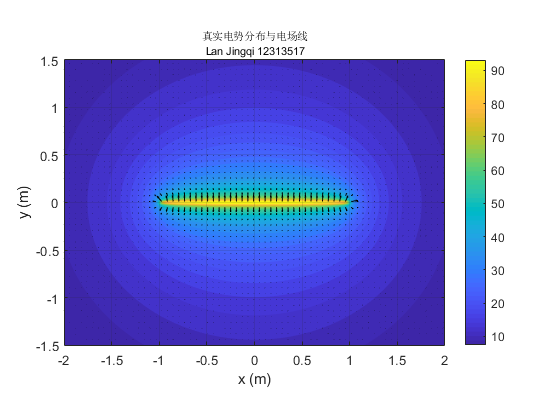

k = 9e9;
lambda = 1e-9;
x1 = -1; x2 = 1;
y_line = 0;

[X, Y] = meshgrid(linspace(-2, 2, 200), linspace(-1.5, 1.5, 150));
dx = X(1,2) - X(1,1);
dy = Y(2,1) - Y(1,1);

phi_real = zeros(size(X));
% 定义被积函数（匿名函数，用于数值积分）
f = @(x, xi, yi) 1./sqrt((xi - x).^2 + (yi - y_line).^2);

for i = 1:numel(X)
    xi = X(i);  % 当前场点的x坐标
    yi = Y(i);  % 当前场点的y坐标
    % 数值积分（替代符号积分int）
    phi_real(i) = k * lambda * integral(@(x) f(x, xi, yi), x1, x2);
end

[Ex_real, Ey_real] = gradient(-phi_real, dx, dy);

figure;
contourf(X, Y, phi_real, 40, 'LineColor','none');
colorbar; hold on;
quiver(X(1:3:end,1:3:end), Y(1:3:end,1:3:end), ...
       Ex_real(1:3:end,1:3:end), Ey_real(1:3:end,1:3:end), 'k');
% 修正：字体大小用键值对 'FontSize', 8 指定
title({'真实电势分布与电场线', 'Lan Jingqi 12313517'}, 'FontSize', 8);
xlabel('x (m)'); ylabel('y (m)');
axis equal tight; grid on;

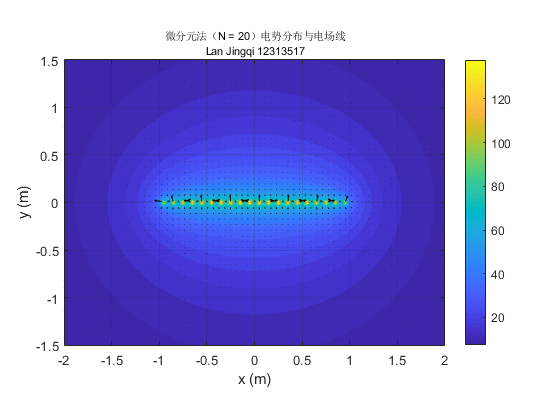

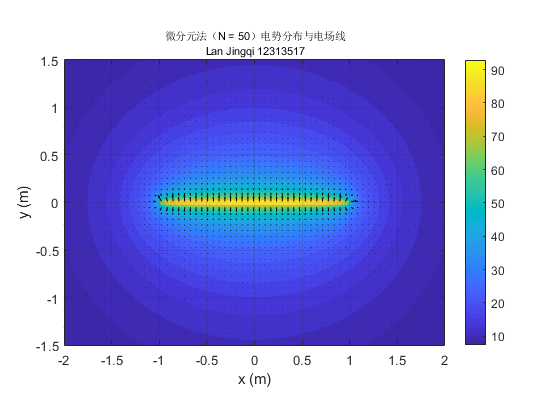

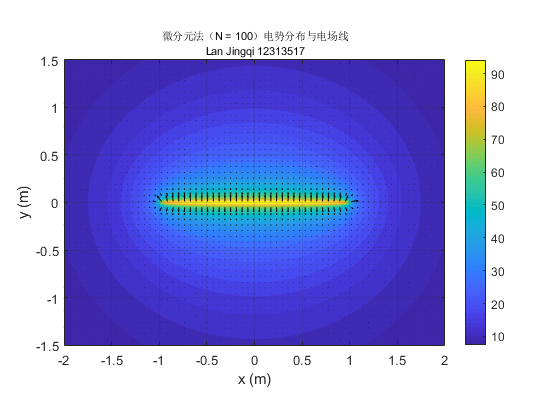


for N = [20, 50, 100]
    phi_approx = zeros(size(X));
    dx_seg = (x2 - x1) / N;
    x_seg = linspace(x1, x2, N+1);

    for i = 1:numel(X)
        for j = 1:N
            x_mid = (x_seg(j) + x_seg(j+1)) / 2;
            r = sqrt((X(i) - x_mid).^2 + (Y(i) - y_line).^2);
            phi_approx(i) = phi_approx(i) + k * lambda * dx_seg ./ r;
        end
    end

    [Ex_approx, Ey_approx] = gradient(-phi_approx, dx, dy);

    figure;
    contourf(X, Y, phi_approx, 40, 'LineColor','none');
    colorbar; hold on;
    quiver(X(1:3:end,1:3:end), Y(1:3:end,1:3:end), ...
           Ex_approx(1:3:end,1:3:end), Ey_approx(1:3:end,1:3:end), 'k');
    % 修正：字体大小用键值对指定
    title({['微分元法（N = ', num2str(N), '）电势分布与电场线'], 'Lan Jingqi 12313517'}, 'FontSize', 8);
    xlabel('x (m)'); ylabel('y (m)');
    axis equal tight; grid on;
end

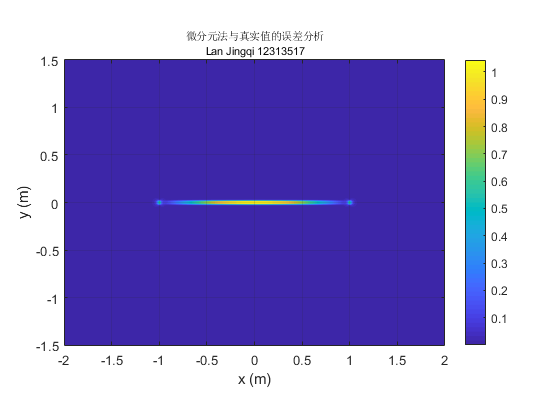


error = abs(phi_real - phi_approx);
figure;
contourf(X, Y, error, 40, 'LineColor','none');
colorbar;
% 修正：字体大小用键值对指定
title({['微分元法与真实值的误差分析'], 'Lan Jingqi 12313517'}, 'FontSize', 8);
xlabel('x (m)'); ylabel('y (m)');
axis equal tight; 
grid on;